% Dataset and descriptor foldes
DATASET_FOLDER = 'C:\Users\Alpas\OneDrive - University of Surrey\EEE3032 - Assignment\msrc_objcategimagedatabase_v2';
DESCRIPTOR_FOLDER = 'C:\Users\Alpas\OneDrive - University of Surrey\EEE3032 - Assignment\descriptors';

% Descriptor Subfolders
GLOBAL_AVERAGE_RGB_FOLDER='globalRGBaverage';
GLOBAL_RGB_HISTOGRAM_FOLDER='globalRGBhisto';
SPATIAL_GRID_FOLDER='spatialGrid';
EDGE_ORIENTATION='edgeOrientation';

SHOW=15; % Show top 15 results

% Pick an image at random to be the query
NIMG=length(dir(fullfile([DATASET_FOLDER,'/Images/*.bmp'])));   % number of images in collection
% queryimg=floor(rand()*NIMG);                                    % index of a random image
% queryimg = 323; % Sheep
 queryimg = 417; % Plane

% Minkowski Distance
q = 1.5;

# Global Avearge Colour

% Load Descriptors
% queryimg = 331; % Sky
[allfiles, ALLFILES, ALLFEAT] = LoadDescriptors(DATASET_FOLDER, DESCRIPTOR_FOLDER, GLOBAL_AVERAGE_RGB_FOLDER);

## PCA

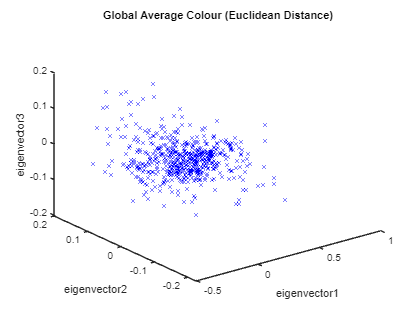

% Build eigen model
[~, eigenDeflated, ALLFEATPCA] = BuildEigenmodel(ALLFEAT);
figure('Name',"Global Average Colour (Euclidean Distance)",'NumberTitle','off'); 
PlotPCA(ALLFEATPCA); 
title("Global Average Colour (Euclidean Distance)");

## Showcase

### Euclidean Distance

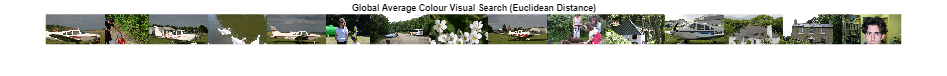

dstAll = EuclideanDistance("Global Average Colour Visual Search (Euclidean Distance)", queryimg, ALLFEAT, SHOW, ALLFILES);

Precision: 0.285714
Recall: 0.137931
Average Precision 0.169900

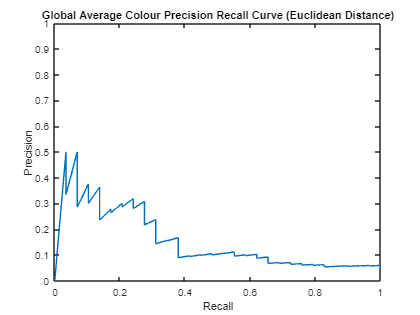

PrecisionRecallCalculateAndDisplay("Global Average Colour Precision Recall Curve (Euclidean Distance)", allfiles, NIMG, dstAll, SHOW);

### Manhattan Distance

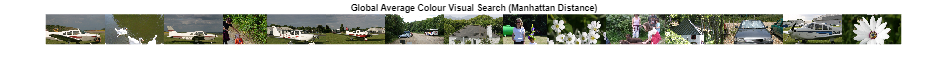

dstAll = ManhattanDistance("Global Average Colour Visual Search (Manhattan Distance)", queryimg, ALLFEAT, SHOW, ALLFILES);

Precision: 0.285714
Recall: 0.137931
Average Precision 0.159375

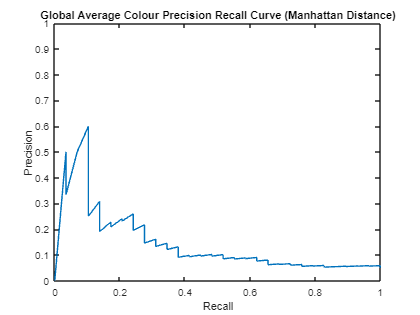

PrecisionRecallCalculateAndDisplay("Global Average Colour Precision Recall Curve (Manhattan Distance)", allfiles, NIMG, dstAll, SHOW);

### Cosine Distance

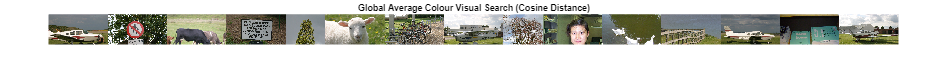

dstAll = CosineDistance("Global Average Colour Visual Search (Cosine Distance)", queryimg, ALLFEAT, SHOW, ALLFILES);

Precision: 0.214286
Recall: 0.103448
Average Precision 0.152042

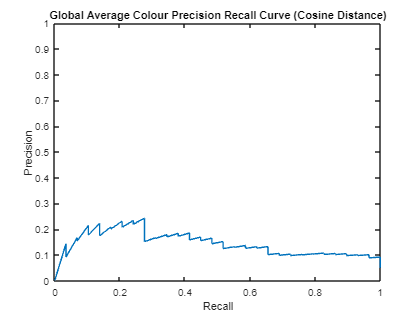

PrecisionRecallCalculateAndDisplay("Global Average Colour Precision Recall Curve (Cosine Distance)", allfiles, NIMG, dstAll, SHOW);

### Minkowski Distance

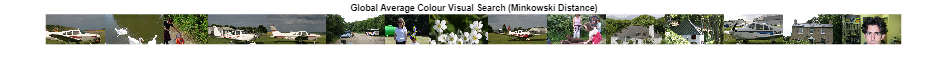

dstAll = MinkowskiDistance("Global Average Colour Visual Search (Minkowski Distance)", queryimg, ALLFEAT, q, SHOW, ALLFILES);

Precision: 0.285714
Recall: 0.137931
Average Precision 0.154946

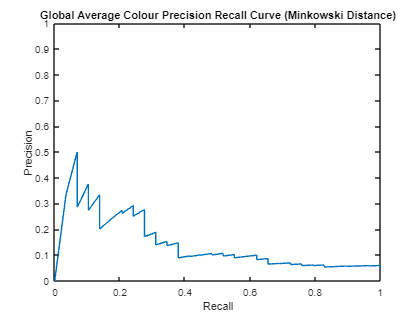

PrecisionRecallCalculateAndDisplay("Global Average Colour Precision Recall Curve (Minkowski Distance)", allfiles, NIMG, dstAll, SHOW);

### Chebyshev Distance

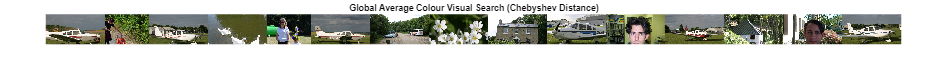

dstAll = ChebyshevDistance("Global Average Colour Visual Search (Chebyshev Distance)", queryimg, ALLFEAT, SHOW, ALLFILES);

Precision: 0.357143
Recall: 0.172414
Average Precision 0.182144

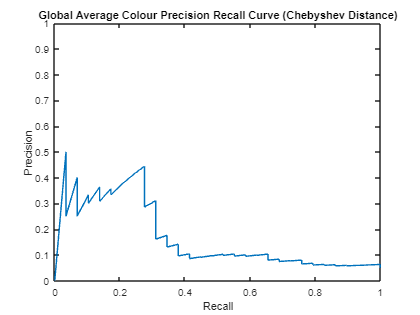

PrecisionRecallCalculateAndDisplay("Global Average Colour Precision Recall Curve (Chebyshev Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Euclidean Distance

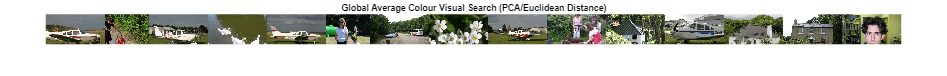

dstAll = EuclideanDistance("Global Average Colour Visual Search (PCA/Euclidean Distance)", queryimg, ALLFEATPCA, SHOW, ALLFILES);

Precision: 0.285714
Recall: 0.137931
Average Precision 0.169900

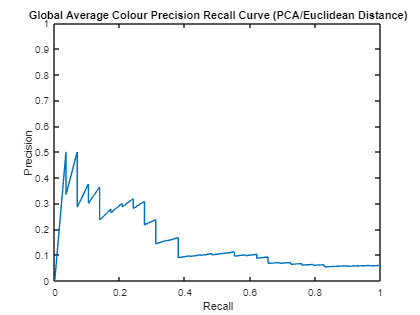

PrecisionRecallCalculateAndDisplay("Global Average Colour Precision Recall Curve (PCA/Euclidean Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Mahalanobis Distance

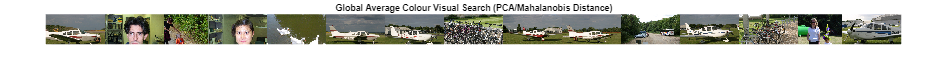

dstAll = MahalanobisDistance("Global Average Colour Visual Search (PCA/Mahalanobis Distance)", queryimg, ALLFEATPCA, eigenDeflated, SHOW, ALLFILES);

Precision: 0.428571
Recall: 0.206897
Average Precision 0.229332

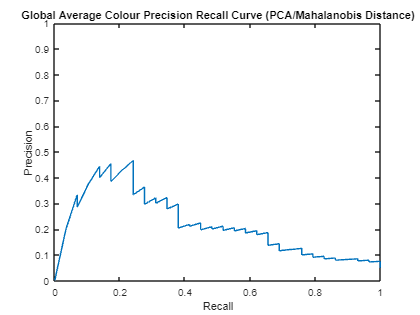

PrecisionRecallCalculateAndDisplay("Global Average Colour Precision Recall Curve (PCA/Mahalanobis Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Manhattan Distance

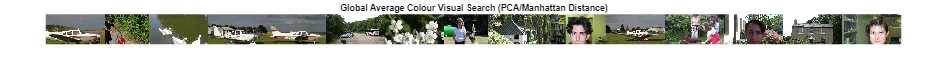

dstAll = ManhattanDistance("Global Average Colour Visual Search (PCA/Manhattan Distance)", queryimg, ALLFEATPCA, SHOW, ALLFILES);

Precision: 0.214286
Recall: 0.103448
Average Precision 0.158314

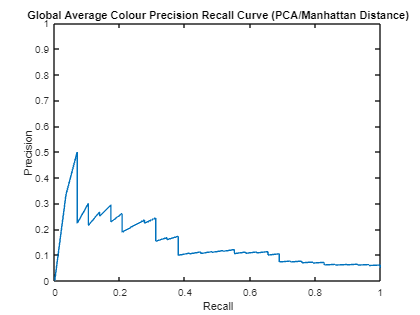

PrecisionRecallCalculateAndDisplay("Global Average Colour Precision Recall Curve (PCA/Manhattan Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Cosine Distance

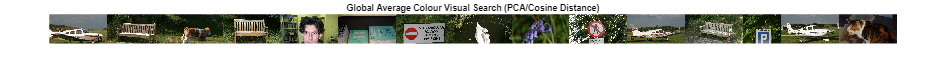

dstAll = CosineDistance("Global Average Colour Visual Search (PCA/Cosine Distance)", queryimg, ALLFEATPCA, SHOW, ALLFILES);

Precision: 0.142857
Recall: 0.068966
Average Precision 0.074757

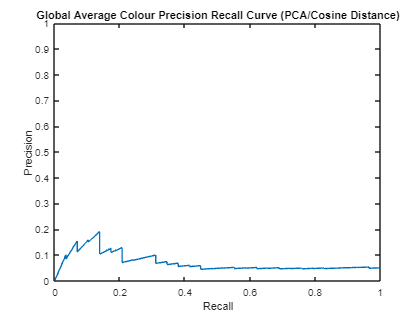

PrecisionRecallCalculateAndDisplay("Global Average Colour Precision Recall Curve (PCA/Cosine Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Minkowski Distance

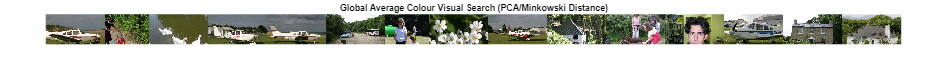

dstAll = MinkowskiDistance("Global Average Colour Visual Search (PCA/Minkowski Distance)", queryimg, ALLFEATPCA, q, SHOW, ALLFILES);

Precision: 0.285714
Recall: 0.137931
Average Precision 0.164704

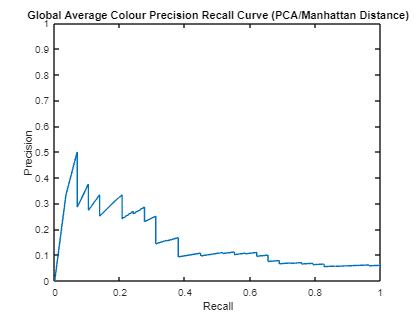

PrecisionRecallCalculateAndDisplay("Global Average Colour Precision Recall Curve (PCA/Manhattan Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Chebyshev Distance

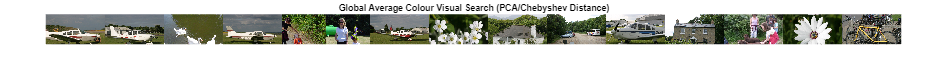

dstAll = ChebyshevDistance("Global Average Colour Visual Search (PCA/Chebyshev Distance)", queryimg, ALLFEATPCA, SHOW, ALLFILES);

Precision: 0.285714
Recall: 0.137931
Average Precision 0.184426

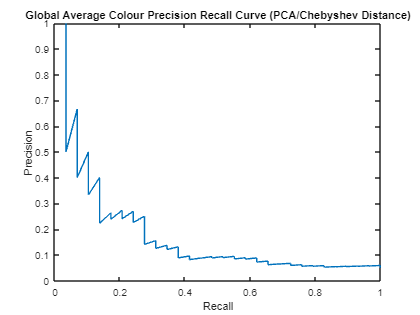

PrecisionRecallCalculateAndDisplay("Global Average Colour Precision Recall Curve (PCA/Chebyshev Distance)", allfiles, NIMG, dstAll, SHOW);

## Global Average Colour - Precision Recall over dataset

% Load Descriptors
[allfiles, ~, ALLFEAT] = LoadDescriptors(DATASET_FOLDER, DESCRIPTOR_FOLDER, GLOBAL_AVERAGE_RGB_FOLDER);
% Build eigen model
[~, eigenDeflated, ALLFEATPCA] = BuildEigenmodel(ALLFEAT);

### Euclidean Distance

EuclideanDistanceOverDataset(NIMG, ALLFEAT, allfiles, SHOW);

Elapsed time is 45.196991 seconds.
Mean Average Precision: 0.120065
Precision: 0.151801
Recall: 0.075493


###  Manhattan Distance

ManhattanDistanceOverDataset(NIMG, ALLFEAT, allfiles, SHOW);

Elapsed time is 45.723601 seconds.
Mean Average Precision: 0.115633
Precision: 0.147208
Recall: 0.073197


### Cosine Distance

CosineDistanceOverDataset(NIMG, ALLFEAT, allfiles, SHOW);

Elapsed time is 48.377281 seconds.
Mean Average Precision: 0.138660
Precision: 0.156394
Recall: 0.077447


### Minkowski Distance

MinkowskiDistanceOverDataset(NIMG, ALLFEAT, q, allfiles, SHOW);

Elapsed time is 49.831232 seconds.
Mean Average Precision: 0.118503
Precision: 0.153372
Recall: 0.076316


### Chebyshev Distance

ChebyshevDistanceOverDataset(NIMG, ALLFEAT, allfiles, SHOW);

Elapsed time is 49.249089 seconds.
Mean Average Precision: 0.122350
Precision: 0.151680
Recall: 0.075500


### PCA/Euclidean Distance

EuclideanDistanceOverDataset(NIMG, ALLFEATPCA, allfiles, SHOW);

Elapsed time is 45.038848 seconds.
Mean Average Precision: 0.120065
Precision: 0.151801
Recall: 0.075493


### PCA/Mahalanobis Distance

MahalanobisDistanceOverDataset(NIMG, ALLFEATPCA, eigenDeflated, allfiles, SHOW);

Elapsed time is 48.041287 seconds.
Mean Average Precision: 0.149413
Precision: 0.179961
Recall: 0.089961


### PCA/Manhattan Distance

ManhattanDistanceOverDataset(NIMG, ALLFEATPCA, allfiles, SHOW);

Elapsed time is 46.831557 seconds.
Mean Average Precision: 0.124403
Precision: 0.151317
Recall: 0.075276


### PCA/Cosine Distance

CosineDistanceOverDataset(NIMG, ALLFEATPCA, allfiles, SHOW);

Elapsed time is 49.377431 seconds.
Mean Average Precision: 0.128087
Precision: 0.152647
Recall: 0.075457


### PCA/Minkowski Distance

MinkowskiDistanceOverDataset(NIMG, ALLFEATPCA, q, allfiles, SHOW);

Elapsed time is 47.192699 seconds.
Mean Average Precision: 0.121853
Precision: 0.151559
Recall: 0.075429


### PCA/Chebyshev Distance

ChebyshevDistanceOverDataset(NIMG, ALLFEATPCA, allfiles, SHOW);

Elapsed time is 44.375294 seconds.
Mean Average Precision: 0.114484
Precision: 0.142615
Recall: 0.070824


# Global RGB Histogram

% Load Descriptors
% queryimg = 565; % Sheep
% queryimg = 541; % Bicycle
% queryimg = 503; % Car;
queryimg=floor(rand()*NIMG);
[allfiles, ALLFILES, ALLFEAT] = LoadDescriptors(DATASET_FOLDER, DESCRIPTOR_FOLDER, GLOBAL_RGB_HISTOGRAM_FOLDER);

## PCA

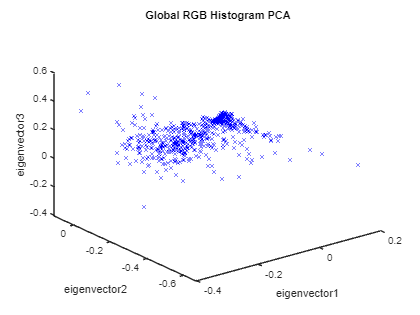

% Build eigen model
[~, eigenDeflated, ALLFEATPCA] = BuildEigenmodel(ALLFEAT);
figure('Name',"Global RGB Histogram PCA",'NumberTitle','off'); PlotPCA(ALLFEATPCA); title("Global RGB Histogram PCA");

## Showcase

### Euclidean Distance

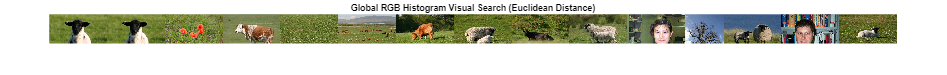

dstAll = EuclideanDistance("Global RGB Histogram Visual Search (Euclidean Distance)", queryimg, ALLFEAT, SHOW, ALLFILES);

Precision: 0.214286
Recall: 0.103448
Average Precision 0.063980

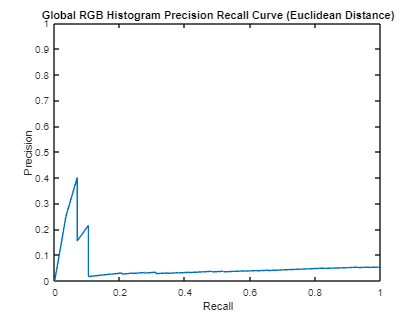

PrecisionRecallCalculateAndDisplay("Global RGB Histogram Precision Recall Curve (Euclidean Distance)", allfiles, NIMG, dstAll, SHOW);

### Manhattan Distance

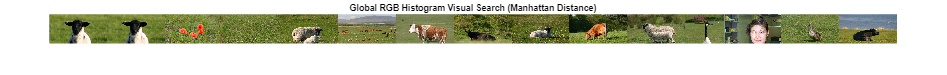

dstAll = ManhattanDistance("Global RGB Histogram Visual Search (Manhattan Distance)", queryimg, ALLFEAT, SHOW, ALLFILES);

Precision: 0.214286
Recall: 0.103448
Average Precision 0.074048

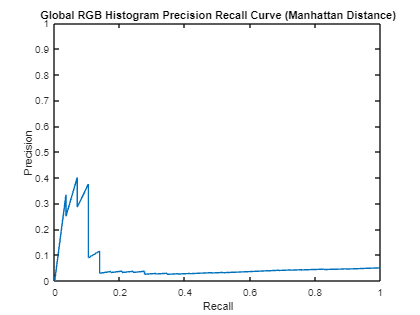

PrecisionRecallCalculateAndDisplay("Global RGB Histogram Precision Recall Curve (Manhattan Distance)", allfiles, NIMG, dstAll, SHOW);

### Cosine Distance

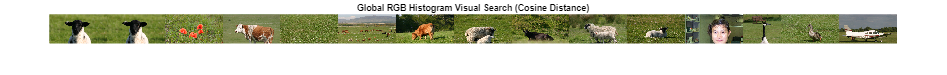

dstAll = CosineDistance("Global RGB Histogram Visual Search (Cosine Distance)", queryimg, ALLFEAT, SHOW, ALLFILES);

Precision: 0.214286
Recall: 0.103448
Average Precision 0.067485

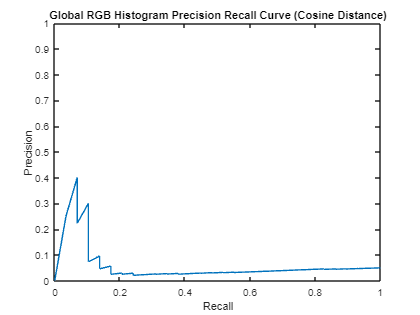

PrecisionRecallCalculateAndDisplay("Global RGB Histogram Precision Recall Curve (Cosine Distance)", allfiles, NIMG, dstAll, SHOW);

### Minkowski Distance

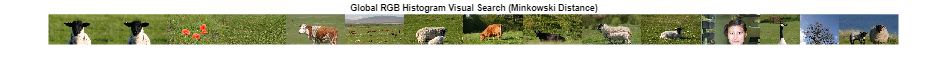

dstAll = MinkowskiDistance("Global RGB Histogram Visual Search (Minkowski Distance)", queryimg, ALLFEAT, q, SHOW, ALLFILES);

Precision: 0.214286
Recall: 0.103448
Average Precision 0.069623

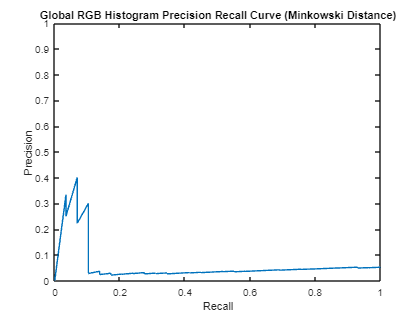

PrecisionRecallCalculateAndDisplay("Global RGB Histogram Precision Recall Curve (Minkowski Distance)", allfiles, NIMG, dstAll, SHOW);

### Chebyshev Distance

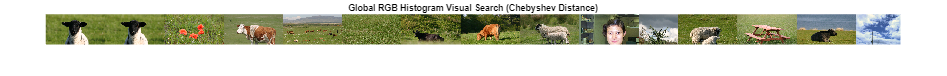

dstAll = ChebyshevDistance("Global RGB Histogram Visual Search (Chebyshev Distance)", queryimg, ALLFEAT, SHOW, ALLFILES);

Precision: 0.142857
Recall: 0.068966
Average Precision 0.065336

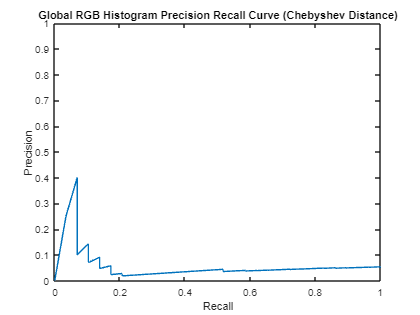

PrecisionRecallCalculateAndDisplay("Global RGB Histogram Precision Recall Curve (Chebyshev Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Euclidean Distance

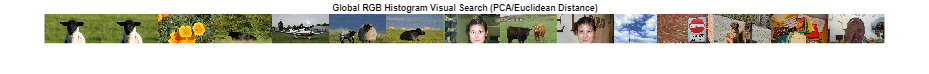

dstAll = EuclideanDistance("Global RGB Histogram Visual Search (PCA/Euclidean Distance)", queryimg, ALLFEATPCA, SHOW, ALLFILES);

Precision: 0.071429
Recall: 0.034483
Average Precision 0.076589

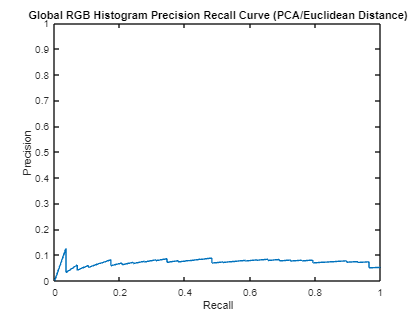

PrecisionRecallCalculateAndDisplay("Global RGB Histogram Precision Recall Curve (PCA/Euclidean Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Mahalanobis Distance

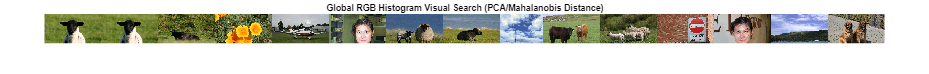

dstAll = MahalanobisDistance("Global RGB Histogram Visual Search (PCA/Mahalanobis Distance)", queryimg, ALLFEATPCA, eigenDeflated, SHOW, ALLFILES);

Precision: 0.071429
Recall: 0.034483
Average Precision 0.076970

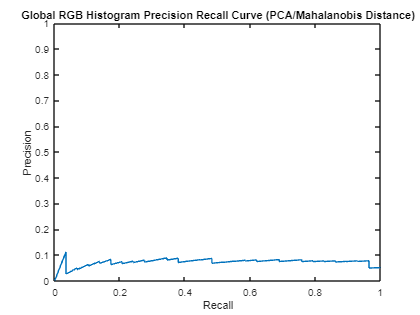

PrecisionRecallCalculateAndDisplay("Global RGB Histogram Precision Recall Curve (PCA/Mahalanobis Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Manhattan Distance

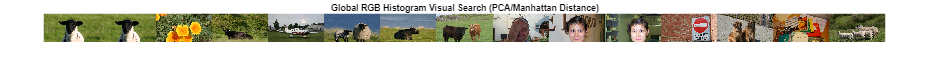

dstAll = ManhattanDistance("Global RGB Histogram Visual Search (PCA/Manhattan Distance)", queryimg, ALLFEATPCA, SHOW, ALLFILES);

Precision: 0.071429
Recall: 0.034483
Average Precision 0.077909

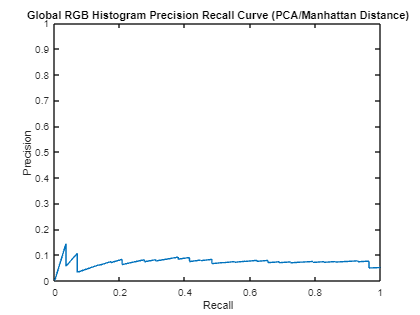

PrecisionRecallCalculateAndDisplay("Global RGB Histogram Precision Recall Curve (PCA/Manhattan Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Cosine Distance

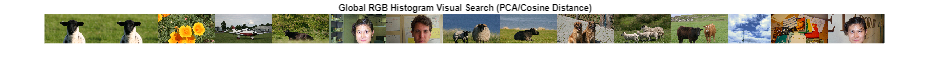

dstAll = CosineDistance("Global RGB Histogram Visual Search (PCA/Cosine Distance)", queryimg, ALLFEATPCA, SHOW, ALLFILES);

Precision: 0.071429
Recall: 0.034483
Average Precision 0.069716

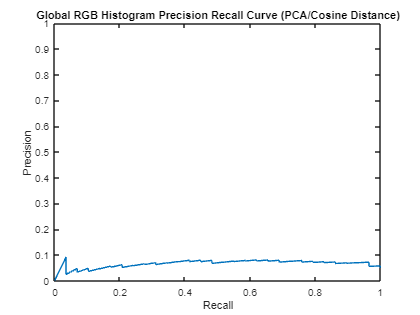

PrecisionRecallCalculateAndDisplay("Global RGB Histogram Precision Recall Curve (PCA/Cosine Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Minkowski Distance

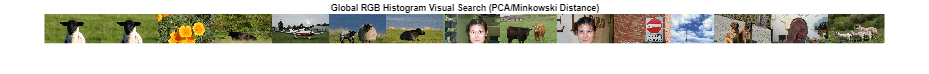

dstAll = MinkowskiDistance("Global RGB Histogram Visual Search (PCA/Minkowski Distance)", queryimg, ALLFEATPCA, q, SHOW, ALLFILES);

Precision: 0.071429
Recall: 0.034483
Average Precision 0.077038

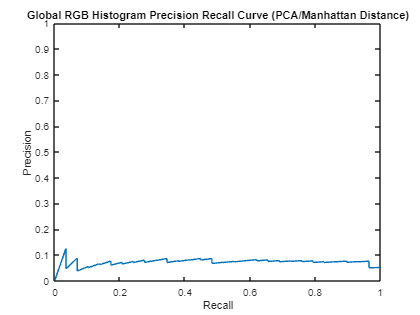

PrecisionRecallCalculateAndDisplay("Global RGB Histogram Precision Recall Curve (PCA/Manhattan Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Chebyshev Distance

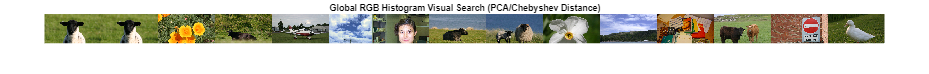

dstAll = ChebyshevDistance("Global RGB Histogram Visual Search (PCA/Chebyshev Distance)", queryimg, ALLFEATPCA, SHOW, ALLFILES);

Precision: 0.071429
Recall: 0.034483
Average Precision 0.073455

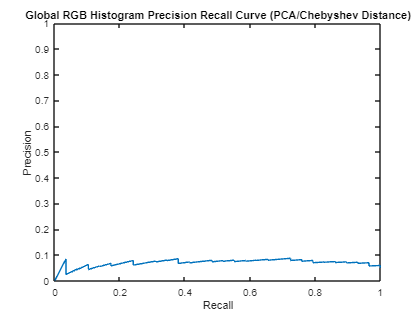

PrecisionRecallCalculateAndDisplay("Global RGB Histogram Precision Recall Curve (PCA/Chebyshev Distance)", allfiles, NIMG, dstAll, SHOW);

## Global RGB Histogram - Precision Recall over dataset

% Load Descriptors
[allfiles, ~, ALLFEAT] = LoadDescriptors(DATASET_FOLDER, DESCRIPTOR_FOLDER, GLOBAL_RGB_HISTOGRAM_FOLDER);
% Build eigen model
[~, eigenDeflated, ALLFEATPCA] = BuildEigenmodel(ALLFEAT);

### Euclidean Distance

EuclideanDistanceOverDataset(NIMG, ALLFEAT, allfiles, SHOW);

Elapsed time is 44.867340 seconds.
Mean Average Precision: 0.130966
Precision: 0.170051
Recall: 0.082554


###  Manhattan Distance

ManhattanDistanceOverDataset(NIMG, ALLFEAT, allfiles, SHOW);

Elapsed time is 44.992110 seconds.
Mean Average Precision: 0.147312
Precision: 0.200749
Recall: 0.097623


### Cosine Distance

CosineDistanceOverDataset(NIMG, ALLFEAT, allfiles, SHOW);

Elapsed time is 50.426589 seconds.
Mean Average Precision: 0.129903
Precision: 0.166667
Recall: 0.080971


### Minkowski Distance

MinkowskiDistanceOverDataset(NIMG, ALLFEAT, q, allfiles, SHOW);

Elapsed time is 62.207274 seconds.
Mean Average Precision: 0.138925
Precision: 0.183587
Recall: 0.089127


### Chebyshev Distance

ChebyshevDistanceOverDataset(NIMG, ALLFEAT, allfiles, SHOW);

Elapsed time is 47.089953 seconds.
Mean Average Precision: 0.113255
Precision: 0.141890
Recall: 0.069182


### PCA/Euclidean Distance

EuclideanDistanceOverDataset(NIMG, ALLFEATPCA, allfiles, SHOW);

Elapsed time is 45.748185 seconds.
Mean Average Precision: 0.099580
Precision: 0.109620
Recall: 0.053071


### PCA/Mahalanobis Distance

MahalanobisDistanceOverDataset(NIMG, ALLFEATPCA, eigenDeflated, allfiles, SHOW);

Elapsed time is 47.148225 seconds.
Mean Average Precision: 0.097437
Precision: 0.109137
Recall: 0.052902


### PCA/Manhattan Distance

ManhattanDistanceOverDataset(NIMG, ALLFEATPCA, allfiles, SHOW);

Elapsed time is 47.089823 seconds.
Mean Average Precision: 0.099466
Precision: 0.112279
Recall: 0.054384


### PCA/Cosine Distance

CosineDistanceOverDataset(NIMG, ALLFEATPCA, allfiles, SHOW);

Elapsed time is 51.363720 seconds.
Mean Average Precision: 0.098997
Precision: 0.104182
Recall: 0.050555


### PCA/Minkowski Distance

MinkowskiDistanceOverDataset(NIMG, ALLFEATPCA, q, allfiles, SHOW);

Elapsed time is 48.250413 seconds.
Mean Average Precision: 0.099915
Precision: 0.110225
Recall: 0.053383


### PCA/Chebyshev Distance

ChebyshevDistanceOverDataset(NIMG, ALLFEATPCA, allfiles, SHOW);

# Edge Orientation Histogram

% Load Descriptors
[allfiles, ALLFILES, ALLFEAT] = LoadDescriptors(DATASET_FOLDER, DESCRIPTOR_FOLDER, GLOBAL_RGB_HISTOGRAM_FOLDER);

## PCA

% Build eigen model
[~, eigenDeflated, ALLFEATPCA] = BuildEigenmodel(ALLFEAT);
figure('Name',"Edge Orientation Histogram PCA",'NumberTitle','off'); PlotPCA(ALLFEATPCA); title("Edge Orientation Histogram PCA");

## Showcase

### Euclidean Distance

dstAll = EuclideanDistance("Edge Orientation Histogram Visual Search (Euclidean Distance)", queryimg, ALLFEAT, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Edge Orientation Histogram Precision Recall Curve (Euclidean Distance)", allfiles, NIMG, dstAll, SHOW);

### Manhattan Distance

dstAll = ManhattanDistance("Edge Orientation Histogram Visual Search (Manhattan Distance)", queryimg, ALLFEAT, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Edge Orientation Histogram Precision Recall Curve (Manhattan Distance)", allfiles, NIMG, dstAll, SHOW);

### Cosine Distance

dstAll = CosineDistance("Edge Orientation Histogram Visual Search (Cosine Distance)", queryimg, ALLFEAT, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Edge Orientation Histogram Precision Recall Curve (Cosine Distance)", allfiles, NIMG, dstAll, SHOW);

### Minkowski Distance

dstAll = MinkowskiDistance("Edge Orientation Histogram Visual Search (Minkowski Distance)", queryimg, ALLFEAT, q, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Edge Orientation Histogram Precision Recall Curve (Minkowski Distance)", allfiles, NIMG, dstAll, SHOW);

### Chebyshev Distance

dstAll = ChebyshevDistance("Edge Orientation Histogram Visual Search (Chebyshev Distance)", queryimg, ALLFEAT, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Edge Orientation Histogram Precision Recall Curve (Chebyshev Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Euclidean Distance

dstAll = EuclideanDistance("Edge Orientation Histogram Visual Search (PCA/Euclidean Distance)", queryimg, ALLFEATPCA, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Edge Orientation Histogram Precision Recall Curve (PCA/Euclidean Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Mahalanobis Distance

dstAll = MahalanobisDistance("Edge Orientation Histogram Visual Search (PCA/Mahalanobis Distance)", queryimg, ALLFEATPCA, eigenDeflated, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Edge Orientation Histogram Precision Recall Curve (PCA/Mahalanobis Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Manhattan Distance

dstAll = ManhattanDistance("Edge Orientation Histogram Visual Search (PCA/Manhattan Distance)", queryimg, ALLFEATPCA, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Edge Orientation Histogram Precision Recall Curve (PCA/Manhattan Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Cosine Distance

dstAll = CosineDistance("Edge Orientation Histogram Visual Search (PCA/Cosine Distance)", queryimg, ALLFEATPCA, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Edge Orientation Histogram Precision Recall Curve (PCA/Cosine Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Minkowski Distance

dstAll = MinkowskiDistance("Edge Orientation Histogram Visual Search (PCA/Minkowski Distance)", queryimg, ALLFEATPCA, q, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Edge Orientation Histogram Precision Recall Curve (PCA/Manhattan Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Chebyshev Distance

dstAll = ChebyshevDistance("Edge Orientation Histogram Visual Search (PCA/Chebyshev Distance)", queryimg, ALLFEATPCA, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Edge Orientation Histogram Precision Recall Curve (PCA/Chebyshev Distance)", allfiles, NIMG, dstAll, SHOW);

## Edge Orientation Histogram - Precision Recall over dataset

% Load Descriptors
[allfiles, ~, ALLFEAT] = LoadDescriptors(DATASET_FOLDER, DESCRIPTOR_FOLDER, EDGE_ORIENTATION);
% Build eigen model
[~, eigenDeflated, ALLFEATPCA] = BuildEigenmodel(ALLFEAT);

### Euclidean Distance

EuclideanDistanceOverDataset(NIMG, ALLFEAT, allfiles, SHOW);

###  Manhattan Distance

ManhattanDistanceOverDataset(NIMG, ALLFEAT, allfiles, SHOW);

### Cosine Distance

CosineDistanceOverDataset(NIMG, ALLFEAT, allfiles, SHOW);

### Minkowski Distance

MinkowskiDistanceOverDataset(NIMG, ALLFEAT, q, allfiles, SHOW);

### Chebyshev Distance

ChebyshevDistanceOverDataset(NIMG, ALLFEAT, allfiles, SHOW);

### PCA/Euclidean Distance

EuclideanDistanceOverDataset(NIMG, ALLFEATPCA, allfiles, SHOW);

### PCA/Mahalanobis Distance

MahalanobisDistanceOverDataset(NIMG, ALLFEATPCA, eigenDeflated, allfiles, SHOW);

### PCA/Manhattan Distance

ManhattanDistanceOverDataset(NIMG, ALLFEATPCA, allfiles, SHOW);

### PCA/Cosine Distance

CosineDistanceOverDataset(NIMG, ALLFEATPCA, allfiles, SHOW);

### PCA/Minkowski Distance

MinkowskiDistanceOverDataset(NIMG, ALLFEATPCA, q, allfiles, SHOW);

### PCA/Chebyshev Distance

ChebyshevDistanceOverDataset(NIMG, ALLFEATPCA, allfiles, SHOW);

# Spatial Grid - Edge Orinetation + Average RGB Colour

% Load Descriptors
queryimg = 437; % Plane
[allfiles, ALLFILES, ALLFEAT] = LoadDescriptors(DATASET_FOLDER, DESCRIPTOR_FOLDER, SPATIAL_GRID_FOLDER);

## PCA

% Build eigen model
[eigenBuild, eigenDeflated, ALLFEATPCA] = BuildEigenmodel(ALLFEAT);
figure('Name',"Spatial Grid PCA",'NumberTitle','off'); PlotPCA(ALLFEATPCA); title("Spatial Grid PCA");

## Showcase

### Euclidean Distance

dstAll = EuclideanDistance("Spatial Grid Visual Search (Euclidean Distance)", queryimg, ALLFEAT, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Spatial Grid Precision Recall Curve (Euclidean Distance)", allfiles, NIMG, dstAll, SHOW);

### Manhattan Distance

dstAll = ManhattanDistance("Spatial Grid Visual Search (Manhattan Distance)", queryimg, ALLFEAT, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Spatial Grid Precision Recall Curve (Manhattan Distance)", allfiles, NIMG, dstAll, SHOW);

### Cosine Distance

dstAll = CosineDistance("Spatial Grid Visual Search (Cosine Distance)", queryimg, ALLFEAT, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Spatial Grid Precision Recall Curve (Cosine Distance)", allfiles, NIMG, dstAll, SHOW);

### Minkowski Distance

dstAll = MinkowskiDistance("Spatial Grid Visual Search (Minkowski Distance)", queryimg, ALLFEAT, q, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Spatial Grid Precision Recall Curve (Minkowski Distance)", allfiles, NIMG, dstAll, SHOW);

### Chebyshev Distance

dstAll = ChebyshevDistance("Spatial Grid Visual Search (Chebyshev Distance)", queryimg, ALLFEAT, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Spatial Grid Precision Recall Curve (Chebyshev Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Euclidean Distance

dstAll = EuclideanDistance("Spatial Grid Visual Search (PCA/Euclidean Distance)", queryimg, ALLFEATPCA, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Spatial Grid Precision Recall Curve (PCA/Euclidean Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Mahalanobis Distance

dstAll = MahalanobisDistance("Spatial Grid Visual Search (PCA/Mahalanobis Distance)", queryimg, ALLFEATPCA, eigenDeflated, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Spatial Grid Precision Recall Curve (PCA/Mahalanobis Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Manhattan Distance

dstAll = ManhattanDistance("Spatial Grid Visual Search (PCA/Manhattan Distance)", queryimg, ALLFEATPCA, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Spatial Grid Precision Recall Curve (PCA/Manhattan Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Cosine Distance

dstAll = CosineDistance("Spatial Grid Visual Search (PCA/Cosine Distance)", queryimg, ALLFEATPCA, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Spatial Grid Precision Recall Curve (PCA/Cosine Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Minkowski Distance

dstAll = MinkowskiDistance("Spatial Grid Visual Search (PCA/Minkowski Distance)", queryimg, ALLFEATPCA, q, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Spatial Grid Precision Recall Curve (PCA/Manhattan Distance)", allfiles, NIMG, dstAll, SHOW);

### PCA/Chebyshev Distance

dstAll = ChebyshevDistance("Spatial Grid Visual Search (PCA/Chebyshev Distance)", queryimg, ALLFEATPCA, SHOW, ALLFILES);
PrecisionRecallCalculateAndDisplay("Spatial Grid Precision Recall Curve (PCA/Chebyshev Distance)", allfiles, NIMG, dstAll, SHOW);

## Spatial Grid - Edge Orinetation + Average RGB Colour - Precision Recall over dataset

% Load Descriptors
[allfiles, ~, ALLFEAT] = LoadDescriptors(DATASET_FOLDER, DESCRIPTOR_FOLDER, SPATIAL_GRID_FOLDER);
% Build eigen model
[~, eigenDeflated, ALLFEATPCA] = BuildEigenmodel(ALLFEAT);

### Euclidean Distance

EuclideanDistanceOverDataset(NIMG, ALLFEAT, allfiles, SHOW);

###  Manhattan Distance

ManhattanDistanceOverDataset(NIMG, ALLFEAT, allfiles, SHOW);

### Cosine Distance

CosineDistanceOverDataset(NIMG, ALLFEAT, allfiles, SHOW);

### Minkowski Distance

MinkowskiDistanceOverDataset(NIMG, ALLFEAT, q, allfiles, SHOW);

### Chebyshev Distance

ChebyshevDistanceOverDataset(NIMG, ALLFEAT, allfiles, SHOW);

### PCA/Euclidean Distance

EuclideanDistanceOverDataset(NIMG, ALLFEATPCA, allfiles, SHOW);

### PCA/Mahalanobis Distance

MahalanobisDistanceOverDataset(NIMG, ALLFEATPCA, eigenDeflated, allfiles, SHOW);

### PCA/Manhattan Distance

ManhattanDistanceOverDataset(NIMG, ALLFEATPCA, allfiles, SHOW);

### PCA/Cosine Distance

CosineDistanceOverDataset(NIMG, ALLFEATPCA, allfiles, SHOW);

### PCA/Minkowski Distance

MinkowskiDistanceOverDataset(NIMG, ALLFEATPCA, q, allfiles, SHOW);

### PCA/Chebyshev Distance

ChebyshevDistanceOverDataset(NIMG, ALLFEATPCA, allfiles, SHOW);

# Helper Functions

function outdisplay = GenerateVisualSearchDisplay(dst, ALLFILES)
    outdisplay=[];
    for i=1:size(dst,1)
        img=imread(ALLFILES{dst(i,2)});
        img=img(1:2:end,1:2:end,:); % make image a quarter size
        img=img(1:81,:,:); % crop image to uniform size vertically (some MSVC images are different heights)
        outdisplay=[outdisplay img];
    end
end


function PlotPCA(ALLFEATPCA)
    plot3(ALLFEATPCA(:,1),ALLFEATPCA(:,2),ALLFEATPCA(:,3),'bx');
    xlabel('eigenvector1');
    ylabel('eigenvector2');
    zlabel('eigenvector3');
end

% function MostPerformantImage()
%     HighestPrecision = 0; HPimg = 0;
%     if HighestPrecision < averagePrecision
%         HighestPrecision = averagePrecision;
%         HPimg = i;
%     end
% end

function MinkowskiDistanceOverDataset(NIMG, ALLFEAT, q, allfiles, SHOW)
    TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
    tic;
    for i=1:NIMG
        dstAll = GetDistance(i, ALLFEAT, @GetMinkowskiDistance, q);
        [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
        TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
    end
    toc;
    fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n', MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);
end

function ChebyshevDistanceOverDataset(NIMG, ALLFEAT, allfiles, SHOW)
    TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
    tic;
    for i=1:NIMG
        dstAll = GetDistance(i, ALLFEAT, @GetChebyshevDistance);
        [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
        TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
    end
    toc;
    fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n', MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);
end

function CosineDistanceOverDataset(NIMG, ALLFEAT, allfiles, SHOW)
    TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
    tic;
    for i=1:NIMG
        dstAll = GetDistance(i, ALLFEAT, @GetCosineDistance);
        [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
        TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
    end
    toc;
    fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n', MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);
end

function ManhattanDistanceOverDataset(NIMG, ALLFEAT, allfiles, SHOW)
    TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
    tic;
    for i=1:NIMG
        dstAll = GetDistance(i, ALLFEAT, @GetManhattanDistance);
        [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
        TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
    end
    toc;
    fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n', MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);
end

function EuclideanDistanceOverDataset(NIMG, ALLFEAT, allfiles, SHOW)
    TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
    tic;
    for i=1:NIMG
        dstAll = GetDistance(i, ALLFEAT, @GetEuclideanDistance);
        [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
        TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
    end
    toc;
    fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n', MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);
end

function MahalanobisDistanceOverDataset(NIMG, ALLFEATPCA, eigenDeflated, allfiles, SHOW)
    TotalPrecision = 0; TotalRecall = 0; MeanAveragePrecision = 0;
    tic;
    for i=1:NIMG
        dstAll = GetDistance(i, ALLFEATPCA, @GetMahalanobisDistance, eigenDeflated.val);
        [~, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
        TotalPrecision = plus(TotalPrecision, precision); TotalRecall = plus(TotalRecall, recall); MeanAveragePrecision = plus(MeanAveragePrecision, averagePrecision);
    end
    toc;
    fprintf('Mean Average Precision: %f\nPrecision: %f\nRecall: %f\n', MeanAveragePrecision/NIMG, TotalPrecision/NIMG, TotalRecall/NIMG);
end

function PrecisionRecallCalculateAndDisplay(text, allfiles, NIMG, dstAll, SHOW)
    [precisionRecallMat, averagePrecision, precision, recall] = PrecisionRecall(allfiles, NIMG, dstAll, SHOW);
    figure('Name',text,'NumberTitle','off');
    plot(precisionRecallMat(:, 2), precisionRecallMat(:, 1));
    axis([0 1 0 1])
    xlabel('Recall');
    ylabel('Precision');
    
    fprintf('Precision: %f\nRecall: %f\nAverage Precision %f', precision, recall, averagePrecision);
    title(text);
end

function dstAll = ChebyshevDistance(text, queryimg, ALLFEATPCA, SHOW, ALLFILES)
    dstAll = GetDistance(queryimg, ALLFEATPCA, @GetChebyshevDistance);
    dst=dstAll(1:SHOW,:);
    
    Display(text, dst, ALLFILES);
end

function dstAll = MinkowskiDistance(text, queryimg, ALLFEATPCA, q, SHOW, ALLFILES)
    dstAll = GetDistance(queryimg, ALLFEATPCA, @GetMinkowskiDistance, q);
    dst=dstAll(1:SHOW,:);
    
    Display(text, dst, ALLFILES);
end

function dstAll = CosineDistance(text, queryimg, ALLFEATPCA, SHOW, ALLFILES)
    dstAll = GetDistance(queryimg, ALLFEATPCA, @GetCosineDistance);
    dst=dstAll(1:SHOW,:);
    
    Display(text, dst, ALLFILES);
end

function dstAll = ManhattanDistance(text, queryimg, ALLFEATPCA, SHOW, ALLFILES)
    dstAll = GetDistance(queryimg, ALLFEATPCA, @GetManhattanDistance);
    dst=dstAll(1:SHOW,:);
    
    Display(text, dst, ALLFILES);
end

function dstAll = MahalanobisDistance(text, queryimg, ALLFEATPCA, eigenDeflated, SHOW, ALLFILES)
    dstAll = GetDistance(queryimg, ALLFEATPCA, @GetMahalanobisDistance, eigenDeflated.val);
    dst=dstAll(1:SHOW,:);
    
    Display(text, dst, ALLFILES);
end

function dstAll = EuclideanDistance(text, queryimg, ALLFEATPCA, SHOW, ALLFILES)
    dstAll = GetDistance(queryimg, ALLFEATPCA, @GetEuclideanDistance);
    dst=dstAll(1:SHOW,:);
    
    Display(text, dst, ALLFILES);
end

function Display(text, dst, ALLFILES)
    figure('Name',text,'NumberTitle','off');
    imshow(GenerateVisualSearchDisplay(dst, ALLFILES)); axis off;
    title(text);
end